initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.7.4).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configur

TAC125Model = readCbModel('iMF721_SMBL3FBC2.xml');

The model contains 1 errors.

Error encountered during read.



%TAC125Model = checkCobraModelUnique(TAC125Model, 'T')
FBAsolutionAsIs = optimizeCbModel(TAC125Model,'max');
GrowthAllEXOpen = FBAsolutionAsIs.f

GrowthAllEXOpen = 1.6834e+03

EX_reactions= TAC125Model.rxns(~cellfun(@isempty, regexp(TAC125Model.rxns,'^EX_')));
NumberOfEXReactions = length(EX_reactions)

NumberOfEXReactions = 87

TAC125Model = changeRxnBounds(TAC125Model, EX_reactions, 0, 'l');
FBAsolutionNoEX = optimizeCbModel(TAC125Model,'max');
FBAsolutionAllClosed = FBAsolutionNoEX.f

FBAsolutionAllClosed = 7.9386e-11

RxnListExchangeSchatz = { 'EX_cpd00254_e' , 'EX_cpd00012_e' , 'EX_cpd00971_e' , 'EX_cpd00067_e' , 'EX_cpd00063_e' , 'EX_cpd00048_e' , 'EX_cpd00205_e' , 'EX_cpd00099_e' , 'EX_cpd00009_e' , 'EX_cpd00013_e' , 'EX_cpd10515_e',  'EX_cpd00209_e' };
TAC125Model = changeRxnBounds(TAC125Model, RxnListExchangeSchatz, -1000, 'l');

SchatzCompunds = strrep(RxnListExchangeSchatz, 'EX_', '');
SchatzCompunds = strrep(SchatzCompunds, '(e)','[e]');
SchatzCompunds = strrep(SchatzCompunds, '_c','c]');

SchatzMatched = TAC125Model.mets(ismember(TAC125Model.mets, SchatzCompunds'));
SchatzMatchedNames = TAC125Model.metNames(ismember(TAC125Model.mets, SchatzCompunds'));
SchatzMatchedLB = TAC125Model.lb(findRxnIDs(TAC125Model, RxnListExchangeSchatz));
SchatzMatchedlUB = TAC125Model.ub(findRxnIDs(TAC125Model, RxnListExchangeSchatz));

table(SchatzMatched, SchatzMatchedNames)


ans =

  0×2 empty table



table(RxnListExchangeSchatz', SchatzMatchedlUB, SchatzMatchedLB)

ans = 12×3 table
         Var1          SchatzMatchedlUB    SchatzMatchedLB
    _______________    ________________    _______________

    'EX_cpd00254_e'         10000               -1000     
    'EX_cpd00012_e'         10000               -1000     
    'EX_cpd00971_e'         10000               -1000     
    'EX_cpd00067_e'         10000               -1000     
    'EX_cpd00063_e'         10000               -1000     
    'EX_cpd00048_e'         10000               -1000     
    'EX_cpd00205_e'         10000               -1000     
    'EX_cpd00099_e'         10000               -1000     
    'EX_cpd00009_e'         10000               -1000     
    'EX_cpd00013_e'         10000               -1000     
    'EX_cpd10515_e'         10000               -1000     
    'EX_cpd00209_e'             0               -1000     




LeuGrowthRateExp = 0.10;
GluGrowthRateExp = 0.34;
AlaGrowthRateExp = 0.25;
AspGrowthRateExp = 0.20;
GGGrowthRateExp = 1.1;


LeuUtilizationRate = 0.1/(5.4/5)/131.17*1000;
GluUtilizationRate = 0.34/(4.4/6.5)/147.13*1000;
AspUtilizationRate = 0.25/(3.6/5.1)/133.11*1000;
AlaUtilizationRate = 0.20/(2.1/3.4)/89.09*1000;

TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00107_e', -LeuUtilizationRate, 'l');
FBAsolutionSchatzLeu = optimizeCbModel(TAC125Model,'max');
SimulationLeu = FBAsolutionSchatzLeu.f;  
TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00107_e', 0, 'l');

TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00023_e', -3.3, 'l');
FBAsolutionSchatzGlu = optimizeCbModel(TAC125Model,'max');
SimulationGlu = FBAsolutionSchatzGlu.f;  
TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00023_e', 0, 'l');

TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00035_e', -AlaUtilizationRate, 'l');
FBAsolutionSchatzAla = optimizeCbModel(TAC125Model,'max');
SimulationAla = FBAsolutionSchatzAla.f;  
TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00035_e', 0, 'l');

TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00041_e', -AspUtilizationRate , 'l');
FBAsolutionSchatzAsp = optimizeCbModel(TAC125Model,'max');
SimulationAsp = FBAsolutionSchatzAsp.f  

SimulationAsp = 0.2367

TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00041_e', 0, 'l');


table(LeuUtilizationRate, SimulationLeu, LeuGrowthRateExp)

ans = 1×3 table
    LeuUtilizationRate    SimulationLeu    LeuGrowthRateExp
    __________________    _____________    ________________

          0.7059            0.094189             0.1       


table(GluUtilizationRate, SimulationGlu, GluGrowthRateExp)

ans = 1×3 table
    GluUtilizationRate    SimulationGlu    GluGrowthRateExp
    __________________    _____________    ________________

          3.4138             0.36694             0.34      


table(AlaUtilizationRate, SimulationAla, AlaGrowthRateExp)

ans = 1×3 table
    AlaUtilizationRate    SimulationAla    AlaGrowthRateExp
    __________________    _____________    ________________

          3.6346             0.24249             0.25      


table(AspUtilizationRate, SimulationAsp, AspGrowthRateExp)

ans = 1×3 table
    AspUtilizationRate    SimulationAsp    AspGrowthRateExp
    __________________    _____________    ________________

          2.6607             0.23668             0.2       



%Set GG simulation

TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00023_e', -0, 'l');
TAC125Model = changeRxnBounds(TAC125Model,  'EX_cpd00222_e', -0, 'l');
FBAsolutionSchatzGG= optimizeCbModel(TAC125Model,'max');
SimulationGG = FBAsolutionSchatzGG.f

SimulationGG = 1.1911e-12

ErrorsInExp = [0.01, 0.03, 0.02, 0.25, 0.03]

ErrorsInExp =     0.0100    0.0300    0.0200    0.2500    0.0300


ModelGR = [SimulationLeu, SimulationGlu, SimulationAla, SimulationAsp, SimulationGG ]

ModelGR =     0.0942    0.3669    0.2425    0.2367    0.0000


ExperimentalGR = [LeuGrowthRateExp, GluGrowthRateExp, AlaGrowthRateExp, AspGrowthRateExp, GGGrowthRateExp ]

ExperimentalGR =     0.1000    0.3400    0.2500    0.2000    1.1000


Combined = [ModelGR(:), ExperimentalGR(:)]

Combined =     0.0942    0.1000
    0.3669    0.3400
    0.2425    0.2500
    0.2367    0.2000
    0.0000    1.1000


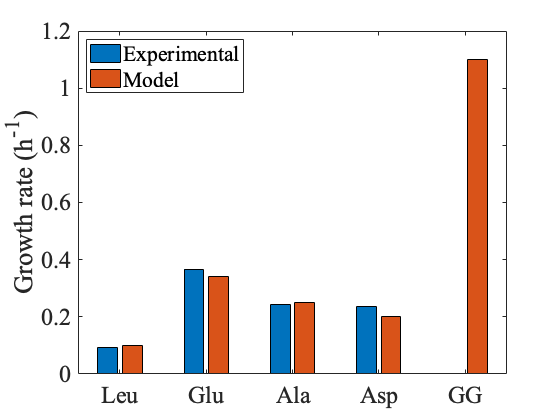

bar(Combined)

ylabel('Growth rate (h^-^1)')
xticklabels({'Leu', 'Glu', 'Ala', 'Asp', 'GG'})
set(gca,'FontName','Times','fontsize',24)
legend('Experimental','Model', 'Location','northwest')


AAExchange = { 'EX_cpd00254_e' , 'EX_cpd00012_e' , 'EX_cpd00971_e' , 'EX_cpd00067_e' , 'EX_cpd00063_e' , 'EX_cpd00048_e' , 'EX_cpd00205_e' , 'EX_cpd00099_e' , 'EX_cpd00009_e' , 'EX_cpd00013_e' , 'EX_cpd10515_e',  'EX_cpd00209_e' };

RxnListExchangeAA = {'EX_cpd00119_e' , 'EX_cpd00322_e' , 'EX_cpd00107_e' , 'EX_cpd00039_e' ,'EX_cpd00060_e' , 'EX_cpd00066_e' ,  'EX_cpd00161_e' , 'EX_cpd00065_e' , 'EX_cpd00156_e', 'EX_cpd00035_e' , 'EX_cpd00051_e' , 'EX_cpd00132_e'  ,  'EX_cpd00041_e' , 'EX_cpd00084_e', 'EX_cpd00023_e' , 'EX_cpd00053_e' , 'EX_cpd00033_e' , 'EX_cpd00064_e' , 'EX_cpd00129_e'  'EX_cpd00054_e' , 'EX_cpd00069_e'}

RxnListExchangeAA = 1×21 cell array
    {'EX_cpd00119_e'}    {'EX_cpd00322_e'}    {'EX_cpd00107_e'}    {'EX_cpd00039_e'}    {'EX_cpd00060_e'}    {'EX_cpd00066_e'}    {'EX_cpd00161_e'}    {'EX_cpd00065_e'}    {'EX_cpd00156_e'}    {'EX_cpd00035_e'}    {'EX_cpd00051_e'}    {'EX_cpd00132_e'}    {'EX_cpd00041_e'}    {'EX_cpd00084_e'}    {'EX_cpd00023_e'}    {'EX_cpd00053_e'}    {'EX_cpd00033_e'}    {'EX_cpd00064_e'}    {'EX_cpd00129_e'}    {'EX_cpd00054_e'}    {'EX_cpd00069_e'}



for i=1:length(RxnListExchangeAA)

    TAC125ModelAA = changeRxnBounds(TAC125Model,  RxnListExchangeAA(i), -1, 'l');
    optimizeCbModel(TAC125ModelAA)
    
end

ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0705
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0534
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.1334
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0754
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 2.4395e-11
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0501
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0719
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0504
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.0890
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0644
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.3377
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0565
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.0667
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0629
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0597
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.0890
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0642
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.0890
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0612
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0635
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.1112
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0588
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.1112
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0680
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.0445
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0564
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.1911e-12
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0647
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.1112
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0585
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 0.0667
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0543
           basis: []
          vars_v: []
               x: [1325×1 double]


ans = struct with fields:
    origStatText: []
               f: 1.0243e-14
               v: [1325×1 double]
               y: [1134×1 double]
               w: [1325×1 double]
               s: [1134×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0518
           basis: []
          vars_v: []
               x: [1325×1 double]
